### **Group: Aleix Granero, Michal Szabó**

**6.10.2021**

## **PRACTICE 2**

### **Problem 2-1. Histogram equalization**

#### **1) Implementing an algorithm that performs the equalization of an input image.**

fprintf("~~~~~~ Problem 1 ~~~~~~")

~~~~~~ Problem 1 ~~~~~~

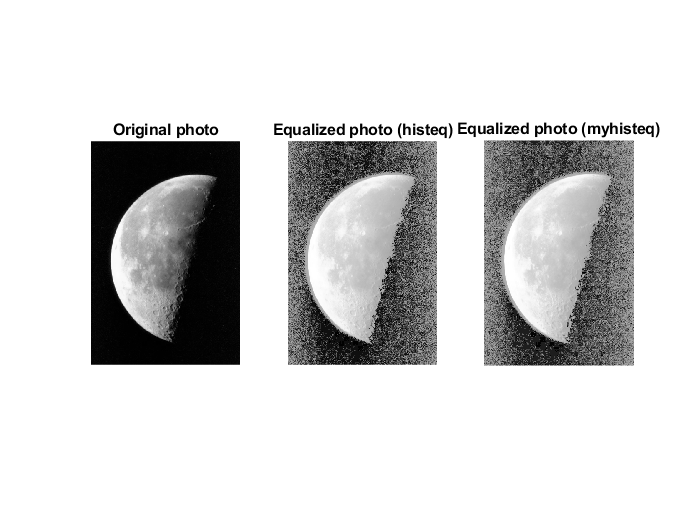


% Input
im = imread('moon.tif');
bins = 255;

% Equalizing images using histeq and the function that we have created
im2 = histeq(im, bins);
im3 = myhisteq(im, bins);
% Show the images
figure
subplot(1,3,1), imshow(im), title("Original photo")
subplot(1,3,2), imshow(im2), title("Equalized photo (histeq)")
subplot(1,3,3), imshow(im3), title("Equalized photo (myhisteq)")

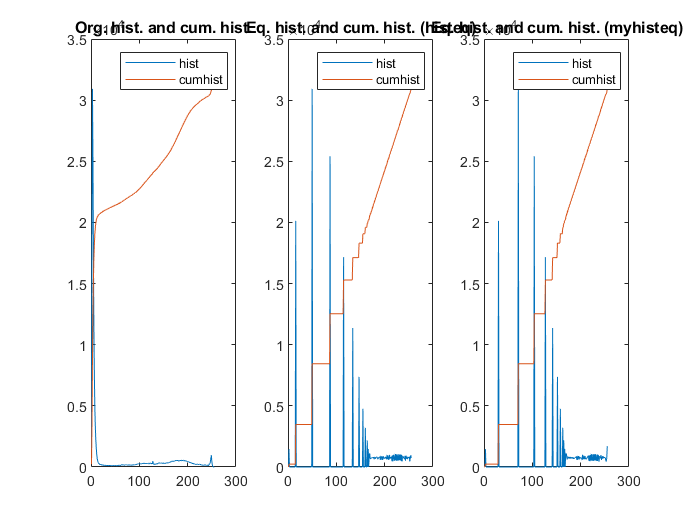


% Original
h1 = imhist(im, bins);       % Counting the occurrence of each pixel value
p1 = h1/numel(im);           % Probabilities of having each pixel
c1 = cumsum(p1)*max(h1);     % Cumulative distribution probability and ajustment
% histeq
h2 = imhist(im2, bins);
p2 = h2/numel(im2);
c2 = cumsum(p2)*max(h2);
% myhisteq
h3 = imhist(im3, bins);
p3 = h3/numel(im3);
c3 = cumsum(p3)*max(h3);

% Displaying corresponding histograms and cumulative histograms
figure
subplot(1,3,1), plot(h1), hold on, plot(c1);
legend('hist','cumhist'), title("Org. hist. and cum. hist.")
subplot(1,3,2), plot(h2); hold on; plot(c2);
legend('hist','cumhist'), title("Eq. hist. and cum. hist. (histeq)")
subplot(1,3,3), plot(h3); hold on; plot(c3);
legend('hist','cumhist'), title("Eq. hist. and cum. hist. (myhisteq)")

**What’s the effect on the resulting histogram peak values when reducing the number of bins?**

With decreasing number of bins, the histogram peak values increase.

#### **2) Comparing myhisteq function and matlab histeq function**

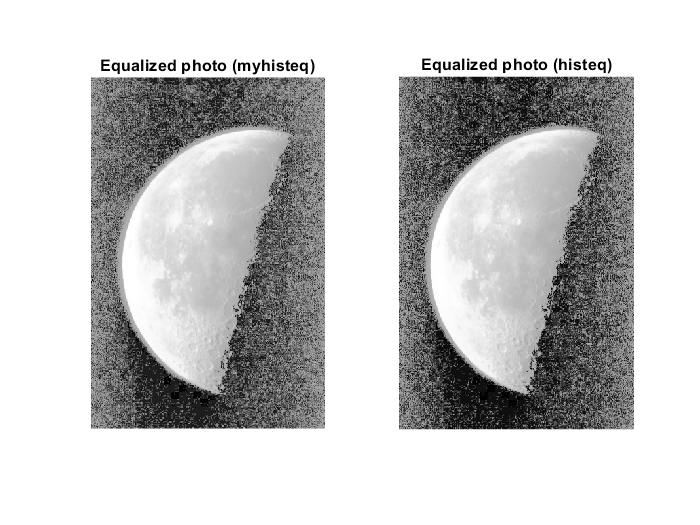

figure
subplot(1,2,1), imshow(im3), title("Equalized photo (myhisteq)")
subplot(1,2,2), imshow(im2), title("Equalized photo (histeq)")

These pictures are not the same but they are very similar. With decreasing number of bins we see bigger difference between them. The difference is hidden in the algorithms. Matlab's algorithm is better optimized than ours.

### **Problem 2-2. Color image equalization**

#### Exercise a)

fprintf("~~ Problem 2 ~~")

~~ Problem 2 ~~

fprintf("2.a)")

2.a)

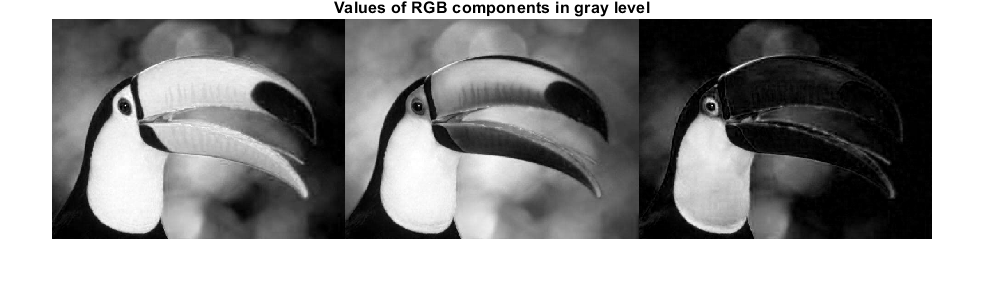


I = imread('tucan1.jpg');               %Charge the image from the folder

[r,g,b] = imsplit(I);                   %Split the image in its RGB components
figure, montage({r,g,b},'Size',[1 3])   %Show the RGB components in gray level
title("Values of RGB components in gray level")

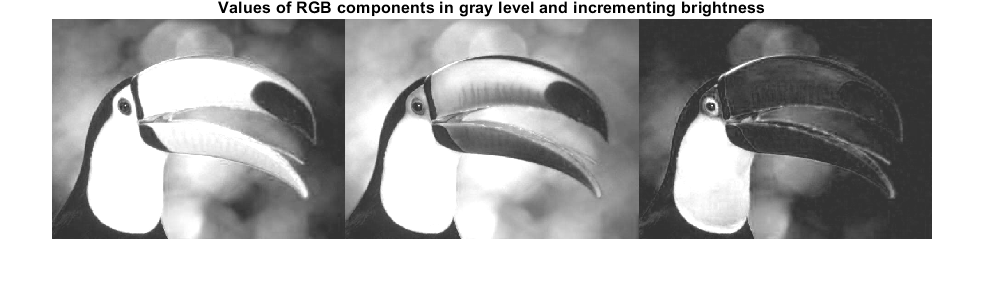


offset = 50;                            %Brightness
r_offset = r+offset; 
g_offset = g+offset; 
b_offset = b+offset;

%Show the RGB components with the incremented brightness
figure, montage({r_offset, g_offset, b_offset},'Size',[1 3])   
title("Values of RGB components in gray level and incrementing brightness")

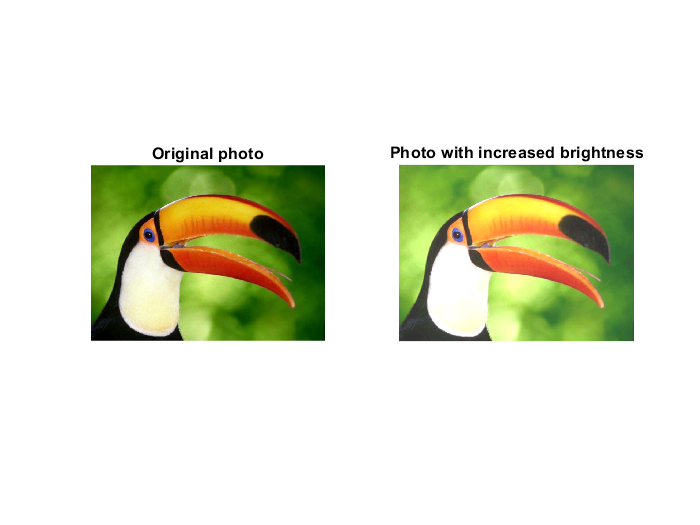


%RGB components are combined using cat function and the final image is shown
figure
subplot(1,2,1); imshow(I)
title("Original photo")
subplot(1,2,2); imshow(cat(3, r_offset, g_offset, b_offset))
title("Photo with increased brightness")

**What happens with original colors when the increment is high enough?**

When we increase the brightness the original colors become more and more lighter.

#### Exercise b)

fprintf("2.b)")

2.b)

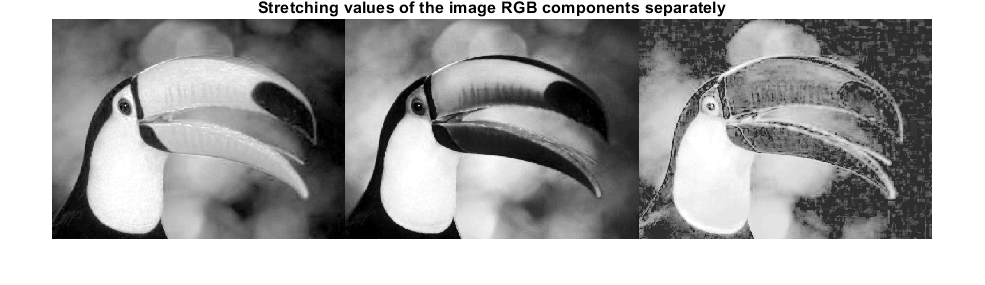


% We equailze each RGB components separately
eq_r = histeq(r);
eq_g = histeq(g);
eq_b = histeq(b);
figure, montage({eq_r, eq_g, eq_b},'Size',[1 3])
title("Stretching values of the image RGB components separately")

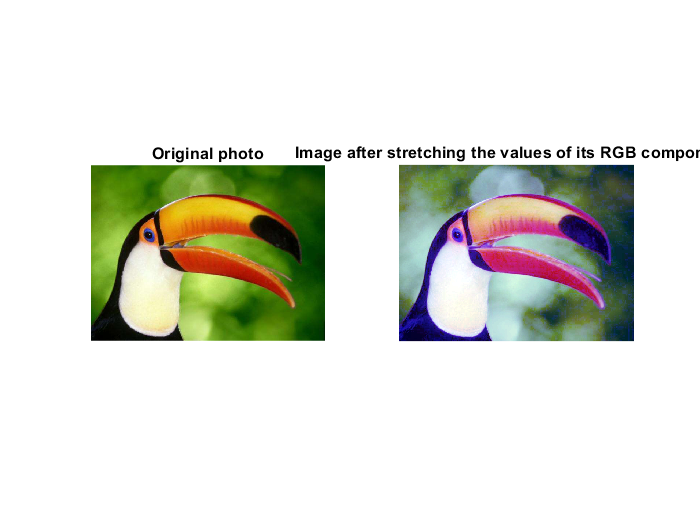


% We combine the equalization of each component
figure
subplot(1,2,1); imshow(I)
title("Original photo")
subplot(1,2,2); imshow(cat(3,eq_r, eq_g, eq_b))
title("Image after stretching the values of its RGB components")

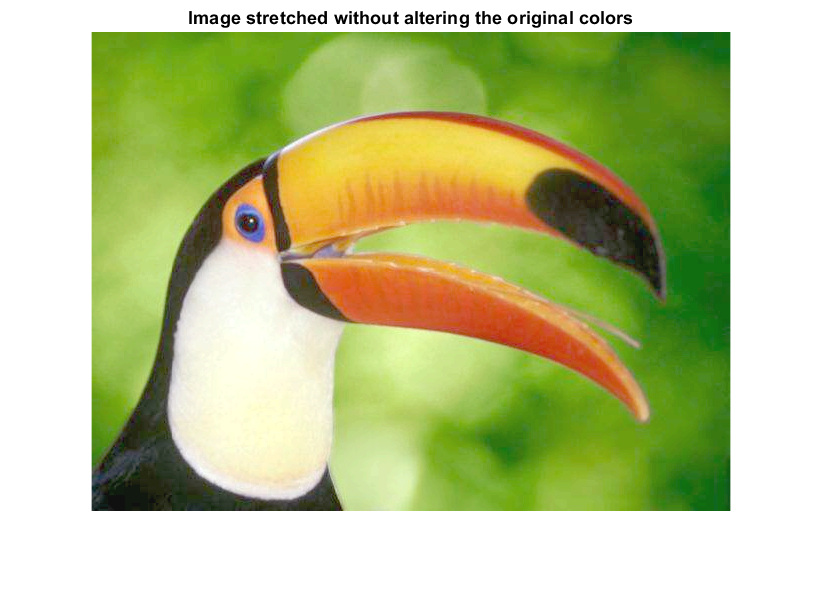


% We apply the equalization directly to the image 
figure, imshow(histeq(I))
title("Image stretched without altering the original colors")

**What happens with original colors?**

Original colors become lighter too.

#### Exercise c)

fprintf("2.c)")

2.c)

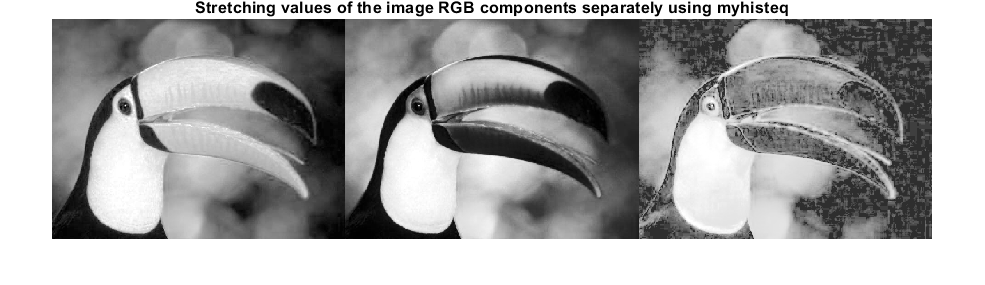


bins = 255;
%We apply our equalization fuction to each RGB components
myeq_r = myhisteq(r, bins);
myeq_g = myhisteq(g, bins);
myeq_b = myhisteq(b, bins);
figure, montage({myeq_r, myeq_g, myeq_b},'Size',[1 3])
title("Stretching values of the image RGB components separately using myhisteq")

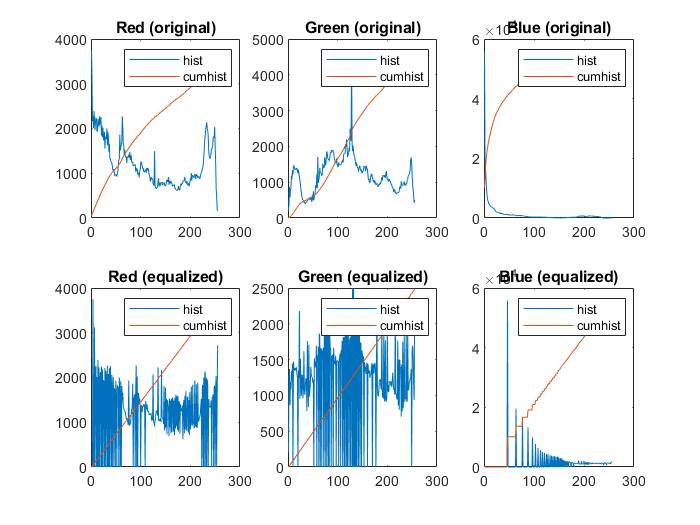


% Histograms of RGB of the original image
% red
h_r = imhist(r, bins);          % Counting the occurrence of each pixel value
p_r = h_r/numel(r);             % Probabilities of having each pixel
c_r = cumsum(p_r)*max(h_r);     % Cumulative distribution probability and ajustment
% green
h_g = imhist(g, bins); 
p_g = h_g/numel(g); 
c_g = cumsum(p_g)*max(h_g);
% blue
h_b = imhist(b, bins); 
p_b = h_b/numel(b); 
c_b = cumsum(p_b)*max(h_b);

% Histograms of RGB equalized by my function
% red
h_myeq_r = imhist(myeq_r, bins);
p_myeq_r = h_myeq_r/numel(myeq_r);
c_myeq_r = cumsum(p_myeq_r)*max(h_myeq_r);
% green
h_myeq_g = imhist(myeq_g, bins); 
p_myeq_g = h_myeq_g/numel(myeq_g); 
c_myeq_g = cumsum(p_myeq_g)*max(h_myeq_g);
% blue
h_myeq_b = imhist(myeq_b, bins); 
p_myeq_b = h_myeq_b/numel(myeq_b); 
c_myeq_b = cumsum(p_myeq_b)*max(h_myeq_b);

figure
subplot(2,3,1), plot(h_r), hold on, plot(c_r);
legend('hist','cumhist'), title("Red (original)")
subplot(2,3,2), plot(h_g); hold on; plot(c_g);
legend('hist','cumhist'), title("Green (original)")
subplot(2,3,3), plot(h_b); hold on; plot(c_b);
legend('hist','cumhist'), title("Blue (original)")

subplot(2,3,4), plot(h_myeq_r), hold on, plot(c_myeq_r);
legend('hist','cumhist'), title("Red (equalized)")
subplot(2,3,5), plot(h_myeq_g); hold on; plot(c_myeq_g);
legend('hist','cumhist'), title("Green (equalized)")
subplot(2,3,6), plot(h_myeq_b); hold on; plot(c_myeq_b);
legend('hist','cumhist'), title("Blue (equalized)")

#### Exercise d)

fprintf("2.d)")

2.d)

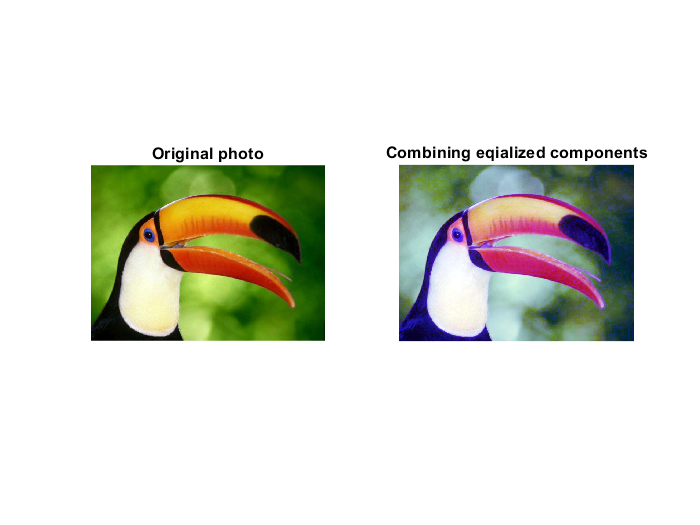


figure
subplot(1,2,1); imshow(I)
title("Original photo")
%RGB components are combined using cat function and the final image is shown
subplot(1,2,2); imshow(cat(3,myeq_r, myeq_g, myeq_b))
title("Combining eqialized components")

**What does it happen to the original image colors when you try to combine the color components again?**

Colors are different and image doesn't look real. This happens because histogram equalization is a non-linear process and involves intensity values of the image not the color components. 

#### Exercise e)

fprintf("2.f)")

2.f)

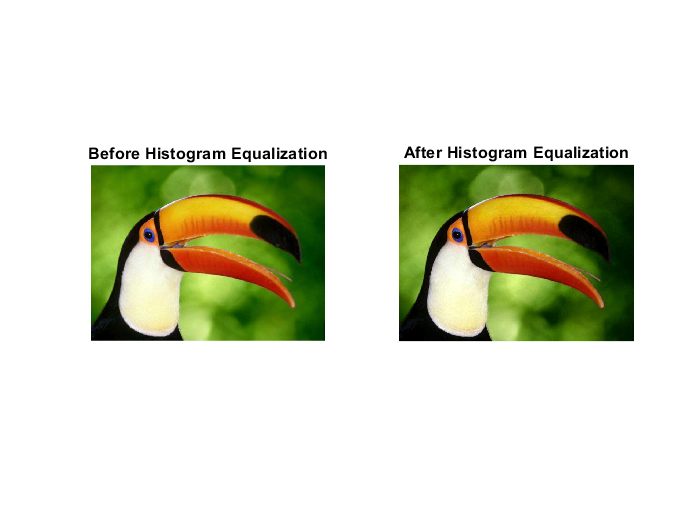


RGB = imread('tucan1.jpg');

% We transfer the picture to different Color space
HSV = rgb2hsv(RGB);

% We split the the HSV image to each of it's components
[h,s,v] = imsplit(HSV);

% We equalize the VALUE component of the HSV image
v2 = histeq(v);

% We create a new image with equalized VALUE component
HSV2 = cat(3,h, s, v2);

% We change the image back to RGB Color space
RGB2 = hsv2rgb(HSV2);

% We plot the results
figure,
subplot (1,2,1), imshow(RGB); title ('Before Histogram Equalization'); 
subplot (1,2,2), imshow(RGB2); title ('After Histogram Equalization');